图像初始化

clc;clear;
%原始图像
yuan1 = imread('1.png');  
yuan1 = im2double(yuan1);
yuan2 = imread('2.png');
yuan2 = im2double(yuan2);
yuan3 = imread('3.png');
yuan3 = im2double(yuan3);
% 假设你已经有噪声图像
gao1 = imread('gao1.png');  
gao1 = im2double(gao1);
gao2 = imread('gao2.png');
gao2 = im2double(gao2);
gao3 = imread('gao3.png');
gao3 = im2double(gao3);

jiao123 = imread('jiao1.png');  % 假设椒盐噪声图像
jiao123 = im2double(jiao123);
jiao2 = imread('jiao2.png');
jiao2 = im2double(jiao2);
jiao3 = imread('jiao3.png');
jiao3 = im2double(jiao3);

cheng123 = imread('cheng1.png');  % 假设乘性噪声图像
cheng123 = im2double(cheng123);
cheng2 = imread('cheng2.png');
cheng2 = im2double(cheng2);
cheng3 = imread('cheng3.png');
cheng3 = im2double(cheng3);

均值滤波

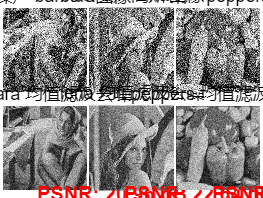

%% 设置均值滤波的滤波器大小
filter_size = 3;  % 3x3的均值滤波器

% 对每个图像应用均值滤波器
gao1_filtered = mean_filter(gao1, filter_size);
gao2_filtered = mean_filter(gao2, filter_size);
gao3_filtered = mean_filter(gao3, filter_size);

jiao123_filtered = mean_filter(jiao123, filter_size);
jiao2_filtered = mean_filter(jiao2, filter_size);
jiao3_filtered = mean_filter(jiao3, filter_size);

cheng123_filtered = mean_filter(cheng123, filter_size);
cheng2_filtered = mean_filter(cheng2, filter_size);
cheng3_filtered = mean_filter(cheng3, filter_size);

%% 计算PSNR值
PSNR_gao1 = psnr(gao1_filtered,yuan1 );
PSNR_gao2 = psnr(gao2_filtered, yuan2);
PSNR_gao3 = psnr(gao3_filtered, yuan3);

PSNR_jiao123 = psnr(jiao123_filtered, yuan1);
PSNR_jiao2 = psnr(jiao2_filtered, yuan2);
PSNR_jiao3 = psnr(jiao3_filtered, yuan3);

PSNR_cheng123 = psnr(cheng123_filtered, yuan1);
PSNR_cheng2 = psnr(cheng2_filtered, yuan2);
PSNR_cheng3 = psnr(cheng3_filtered, yuan3);

%% 将图像和PSNR值传递给函数进行显示
% 高斯噪声
noisy_images_gao = {gao1, gao2, gao3};
denoised_images_gao = {gao1_filtered, gao2_filtered, gao3_filtered};
psnr_values_gao = [PSNR_gao1, PSNR_gao2, PSNR_gao3];
display_multiple_images_with_psnr('高斯噪声', '均值滤波', noisy_images_gao, denoised_images_gao, psnr_values_gao);

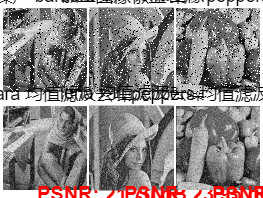


% 椒盐噪声
noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_filtered, jiao2_filtered, jiao3_filtered};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];
display_multiple_images_with_psnr('椒盐噪声', '均值滤波', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

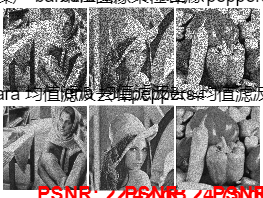


% 乘性噪声
noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_filtered, cheng2_filtered, cheng3_filtered};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];
display_multiple_images_with_psnr('乘性噪声', '均值滤波', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

中值滤波

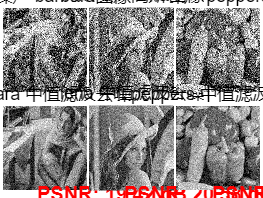

%% 设置中值滤波的滤波器大小
filter_size = 3;  % 3x3的中值滤波器

% 对每个图像应用中值滤波器
gao1_filtered = median_filter(gao1, filter_size);
gao2_filtered = median_filter(gao2, filter_size);
gao3_filtered = median_filter(gao3, filter_size);

jiao123_filtered = median_filter(jiao123, filter_size);
jiao2_filtered = median_filter(jiao2, filter_size);
jiao3_filtered = median_filter(jiao3, filter_size);

cheng123_filtered = median_filter(cheng123, filter_size);
cheng2_filtered = median_filter(cheng2, filter_size);
cheng3_filtered = median_filter(cheng3, filter_size);

%% 计算PSNR值
PSNR_gao1 = psnr(gao1_filtered, yuan1);
PSNR_gao2 = psnr(gao2_filtered, yuan2);
PSNR_gao3 = psnr(gao3_filtered, yuan3);

PSNR_jiao123 = psnr(jiao123_filtered, yuan1);
PSNR_jiao2 = psnr(jiao2_filtered, yuan2);
PSNR_jiao3 = psnr(jiao3_filtered, yuan3);

PSNR_cheng123 = psnr(cheng123_filtered, yuan1);
PSNR_cheng2 = psnr(cheng2_filtered, yuan2);
PSNR_cheng3 = psnr(cheng3_filtered, yuan3);


%% 将图像和PSNR值传递给函数进行显示
% 高斯噪声
noisy_images_gao = {gao1, gao2, gao3};
denoised_images_gao = {gao1_filtered, gao2_filtered, gao3_filtered};
psnr_values_gao = [PSNR_gao1, PSNR_gao2, PSNR_gao3];
display_multiple_images_with_psnr('高斯噪声', '中值滤波', noisy_images_gao, denoised_images_gao, psnr_values_gao);

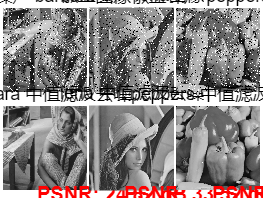


% 椒盐噪声
noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_filtered, jiao2_filtered, jiao3_filtered};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];
display_multiple_images_with_psnr('椒盐噪声', '中值滤波', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

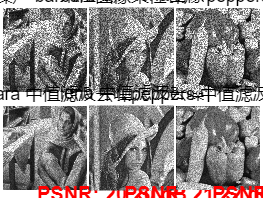


% 乘性噪声
noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_filtered, cheng2_filtered, cheng3_filtered};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];
display_multiple_images_with_psnr('乘性噪声', '中值滤波', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

高斯低通

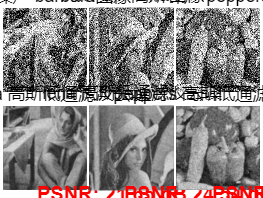

% 设置高斯低通滤波器的参数
D0 = 30;  % 截止频率
sigma = D0 / sqrt(2*log(2)); % 计算标准差，控制滤波器的宽度

% 对每个图像应用高斯低通滤波器
gao1_filtered = gaussian_lowpass_filter(gao1, sigma);
gao2_filtered = gaussian_lowpass_filter(gao2, sigma);
gao3_filtered = gaussian_lowpass_filter(gao3, sigma);

jiao123_filtered = gaussian_lowpass_filter(jiao123, sigma);
jiao2_filtered = gaussian_lowpass_filter(jiao2, sigma);
jiao3_filtered = gaussian_lowpass_filter(jiao3, sigma);

cheng123_filtered = gaussian_lowpass_filter(cheng123, sigma);
cheng2_filtered = gaussian_lowpass_filter(cheng2, sigma);
cheng3_filtered = gaussian_lowpass_filter(cheng3, sigma);

% 计算PSNR值
PSNR_gao1 = psnr(gao1_filtered, yuan1);
PSNR_gao2 = psnr(gao2_filtered, yuan2);
PSNR_gao3 = psnr(gao3_filtered, yuan3);

PSNR_jiao123 = psnr(jiao123_filtered, yuan1);
PSNR_jiao2 = psnr(jiao2_filtered, yuan2);
PSNR_jiao3 = psnr(jiao3_filtered, yuan3);

PSNR_cheng123 = psnr(cheng123_filtered, yuan1);
PSNR_cheng2 = psnr(cheng2_filtered, yuan2);
PSNR_cheng3 = psnr(cheng3_filtered, yuan3);


% 将图像和PSNR值传递给函数进行显示
noisy_images_gao = {gao1, gao2, gao3};
denoised_images_gao = {gao1_filtered, gao2_filtered, gao3_filtered};
psnr_values_gao = [PSNR_gao1, PSNR_gao2, PSNR_gao3];
display_multiple_images_with_psnr('高斯噪声', '高斯低通滤波', noisy_images_gao, denoised_images_gao, psnr_values_gao);

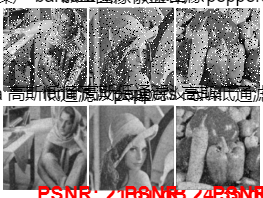


noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_filtered, jiao2_filtered, jiao3_filtered};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];
display_multiple_images_with_psnr('椒盐噪声', '高斯低通滤波', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

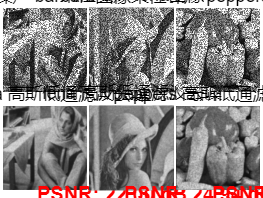


noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_filtered, cheng2_filtered, cheng3_filtered};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];
display_multiple_images_with_psnr('乘性噪声', '高斯低通滤波', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

巴特沃斯低通

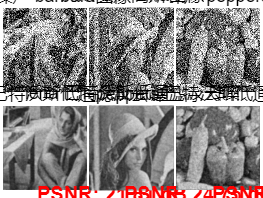

% 设置巴特沃斯低通滤波器的参数
D0 = 30;  % 截止频率
n = 2;    % 滤波器的阶数

% 对每个图像应用巴特沃斯低通滤波器
gao1_filtered = butterworth_lowpass_filter(gao1, D0, n);
gao2_filtered = butterworth_lowpass_filter(gao2, D0, n);
gao3_filtered = butterworth_lowpass_filter(gao3, D0, n);

jiao123_filtered = butterworth_lowpass_filter(jiao123, D0, n);
jiao2_filtered = butterworth_lowpass_filter(jiao2, D0, n);
jiao3_filtered = butterworth_lowpass_filter(jiao3, D0, n);

cheng123_filtered = butterworth_lowpass_filter(cheng123, D0, n);
cheng2_filtered = butterworth_lowpass_filter(cheng2, D0, n);
cheng3_filtered = butterworth_lowpass_filter(cheng3, D0, n);

% 计算每张图的 PSNR
PSNR_gao1 = psnr(gao1_filtered, yuan1);
PSNR_gao2 = psnr(gao2_filtered, yuan2);
PSNR_gao3 = psnr(gao3_filtered, yuan3);

PSNR_jiao123 = psnr(jiao123_filtered, yuan1);
PSNR_jiao2 = psnr(jiao2_filtered, yuan2);
PSNR_jiao3 = psnr(jiao3_filtered, yuan3);

PSNR_cheng123 = psnr(cheng123_filtered, yuan1);
PSNR_cheng2 = psnr(cheng2_filtered, yuan2);
PSNR_cheng3 = psnr(cheng3_filtered, yuan3);

% 将图像和PSNR值传递给函数进行显示
noisy_images_gao = {gao1, gao2, gao3};
denoised_images_gao = {gao1_filtered, gao2_filtered, gao3_filtered};
psnr_values_gao = [PSNR_gao1, PSNR_gao2, PSNR_gao3];

noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_filtered, jiao2_filtered, jiao3_filtered};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];

noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_filtered, cheng2_filtered, cheng3_filtered};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];

% 显示高斯噪声和巴特沃斯低通滤波后的效果
display_multiple_images_with_psnr('高斯噪声', '巴特沃斯低通滤波', noisy_images_gao, denoised_images_gao, psnr_values_gao);

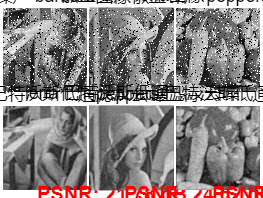

display_multiple_images_with_psnr('椒盐噪声', '巴特沃斯低通滤波', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

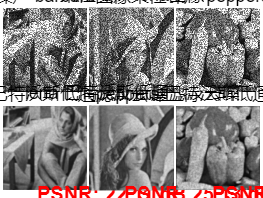

display_multiple_images_with_psnr('乘性噪声', '巴特沃斯低通滤波', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

小波变换

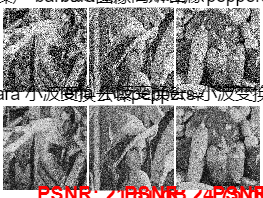


%变换
gao1_denoised = wavelet_denoise(gao1);
gao2_denoised = wavelet_denoise(gao2);
gao3_denoised = wavelet_denoise(gao3);
jiao123_denoised = wavelet_denoise(jiao123);
jiao2_denoised = wavelet_denoise(jiao2);
jiao3_denoised = wavelet_denoise(jiao3);
cheng123_denoised = wavelet_denoise(cheng123);
cheng2_denoised = wavelet_denoise(cheng2);
cheng3_denoised = wavelet_denoise(cheng3);
% 计算每张图的 PSNR
PSNR_gao1 = psnr(gao1_filtered, yuan1);
PSNR_gao2 = psnr(gao2_filtered, yuan2);
PSNR_gao3 = psnr(gao3_filtered, yuan3);

PSNR_jiao123 = psnr(jiao123_filtered, yuan1);
PSNR_jiao2 = psnr(jiao2_filtered, yuan2);
PSNR_jiao3 = psnr(jiao3_filtered, yuan3);

PSNR_cheng123 = psnr(cheng123_filtered, yuan1);
PSNR_cheng2 = psnr(cheng2_filtered, yuan2);
PSNR_cheng3 = psnr(cheng3_filtered, yuan3);

% 将图像和PSNR值传递给函数进行显示
noisy_images = {gao1, gao2, gao3};
denoised_images = {gao1_denoised, gao2_denoised, gao3_denoised};
psnr_values = [PSNR_gao1, PSNR_gao2, PSNR_gao3];

noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_denoised, jiao2_denoised, jiao3_denoised};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];

noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_denoised, cheng2_denoised, cheng3_denoised};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];

display_multiple_images_with_psnr('高斯噪声', '小波变换',noisy_images, denoised_images, psnr_values);

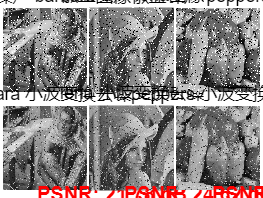

display_multiple_images_with_psnr('椒盐噪声','小波变换', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

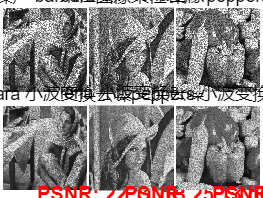

display_multiple_images_with_psnr('乘性噪声', '小波变换',noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

DCT变换

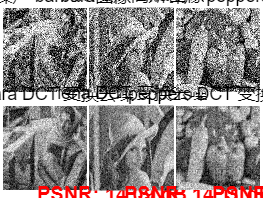

% 设定参数
sigma = 0.25; % 噪声标准差
threshold = 2 * sigma; % 阈值，设定为噪声的2倍

% 对每种噪声类型进行去噪处理
gao1_denoised = DCT_denoising(gao1, threshold);
gao2_denoised = DCT_denoising(gao2, threshold);
gao3_denoised = DCT_denoising(gao3, threshold);

% 计算每张图像的 PSNR
PSNR_gao1 = psnr(gao1_denoised, gao1); % 假设 'gao1' 是原始干净图像
PSNR_gao2 = psnr(gao2_denoised, gao2); % 假设 'gao2' 是原始干净图像
PSNR_gao3 = psnr(gao3_denoised, gao3); % 假设 'gao3' 是原始干净图像

% 计算椒盐噪声图像的 PSNR
jiao123_denoised = DCT_denoising(jiao123, threshold);
jiao2_denoised = DCT_denoising(jiao2, threshold);
jiao3_denoised = DCT_denoising(jiao3, threshold);

PSNR_jiao123 = psnr(jiao123_denoised, jiao123); 
PSNR_jiao2 = psnr(jiao2_denoised, jiao2);
PSNR_jiao3 = psnr(jiao3_denoised, jiao3);

cheng123_denoised = DCT_denoising(cheng123, threshold);
cheng2_denoised = DCT_denoising(cheng2, threshold);
cheng3_denoised = DCT_denoising(cheng3, threshold);

PSNR_cheng123 = psnr(cheng123_denoised, cheng123); 
PSNR_cheng2 = psnr(cheng2_denoised, cheng2);
PSNR_cheng3 = psnr(cheng3_denoised, cheng3);

% 将去噪前后的图像和PSNR值传递给显示函数
noisy_images = {gao1, gao2, gao3};
denoised_images = {gao1_denoised, gao2_denoised, gao3_denoised};
psnr_values = [PSNR_gao1, PSNR_gao2, PSNR_gao3];

noisy_images_jiao = {jiao123, jiao2, jiao3};
denoised_images_jiao = {jiao123_denoised, jiao2_denoised, jiao3_denoised};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];

noisy_images_cheng = {cheng123, cheng2, cheng3};
denoised_images_cheng = {cheng123_denoised, cheng2_denoised, cheng3_denoised};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];

% 显示去噪前后的图像和PSNR值
display_multiple_images_with_psnr('高斯噪声', 'DCT 变换', noisy_images, denoised_images, psnr_values);

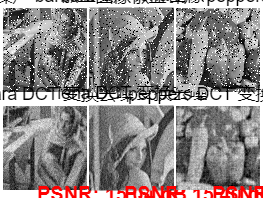

display_multiple_images_with_psnr('椒盐噪声', 'DCT 变换', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

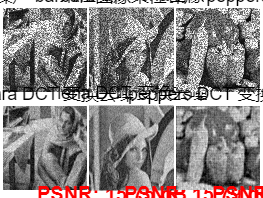

display_multiple_images_with_psnr('乘性噪声', 'DCT 变换', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

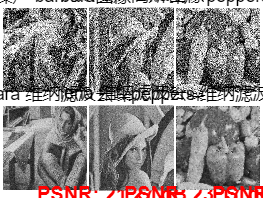

% 假设你已经有了原始图像和加噪图像
% 高斯噪声图像
gao1_noisy = imnoise(gao1, 'gaussian', 0, 0.01);  % 加入高斯噪声
gao2_noisy = imnoise(gao2, 'gaussian', 0, 0.01);  
gao3_noisy = imnoise(gao3, 'gaussian', 0, 0.01); 

% 椒盐噪声图像
jiao123_noisy = imnoise(jiao123, 'salt & pepper', 0.05);  % 加入椒盐噪声
jiao2_noisy = imnoise(jiao2, 'salt & pepper', 0.05);  
jiao3_noisy = imnoise(jiao3, 'salt & pepper', 0.05);  

% 乘性噪声图像
cheng123_noisy = imnoise(cheng123, 'speckle', 0.05);  % 加入乘性噪声
cheng2_noisy = imnoise(cheng2, 'speckle', 0.05);  
cheng3_noisy = imnoise(cheng3, 'speckle', 0.05);  

% 使用 wiener2 进行二维自适应维纳滤波
gao1_denoised = wiener2(gao1_noisy, [5 5]);  % 使用 5x5 的窗口
gao2_denoised = wiener2(gao2_noisy, [5 5]);
gao3_denoised = wiener2(gao3_noisy, [5 5]);

jiao123_denoised = wiener2(jiao123_noisy, [5 5]);
jiao2_denoised = wiener2(jiao2_noisy, [5 5]);
jiao3_denoised = wiener2(jiao3_noisy, [5 5]);

cheng123_denoised = wiener2(cheng123_noisy, [5 5]);
cheng2_denoised = wiener2(cheng2_noisy, [5 5]);
cheng3_denoised = wiener2(cheng3_noisy, [5 5]);

% 计算每张图的 PSNR
PSNR_gao1 = psnr(gao1_denoised, yuan1);
PSNR_gao2 = psnr(gao2_denoised, yuan2);
PSNR_gao3 = psnr(gao3_denoised, yuan3);

PSNR_jiao123 = psnr(jiao123_denoised, yuan1);
PSNR_jiao2 = psnr(jiao2_denoised, yuan2);
PSNR_jiao3 = psnr(jiao3_denoised, yuan3);

PSNR_cheng123 = psnr(cheng123_denoised, yuan1);
PSNR_cheng2 = psnr(cheng2_denoised, yuan2);
PSNR_cheng3 = psnr(cheng3_denoised, yuan3);

% 将图像和PSNR值传递给函数进行显示
noisy_images = {gao1_noisy, gao2_noisy, gao3_noisy};
denoised_images = {gao1_denoised, gao2_denoised, gao3_denoised};
psnr_values = [PSNR_gao1, PSNR_gao2, PSNR_gao3];

noisy_images_jiao = {jiao123_noisy, jiao2_noisy, jiao3_noisy};
denoised_images_jiao = {jiao123_denoised, jiao2_denoised, jiao3_denoised};
psnr_values_jiao = [PSNR_jiao123, PSNR_jiao2, PSNR_jiao3];

noisy_images_cheng = {cheng123_noisy, cheng2_noisy, cheng3_noisy};
denoised_images_cheng = {cheng123_denoised, cheng2_denoised, cheng3_denoised};
psnr_values_cheng = [PSNR_cheng123, PSNR_cheng2, PSNR_cheng3];

% 显示去噪前后的图像和PSNR值
display_multiple_images_with_psnr('高斯噪声', '维纳滤波', noisy_images, denoised_images, psnr_values);

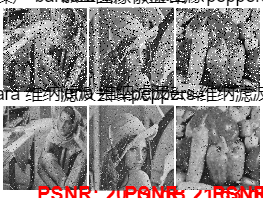

display_multiple_images_with_psnr('椒盐噪声', '维纳滤波', noisy_images_jiao, denoised_images_jiao, psnr_values_jiao);

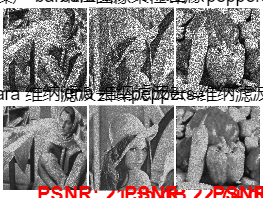

display_multiple_images_with_psnr('乘性噪声', '维纳滤波', noisy_images_cheng, denoised_images_cheng, psnr_values_cheng);

显示

function display_multiple_images_with_psnr(noise_type, transform_method, noisy_images, denoised_images, psnr_values)
    % noise_type: 噪声类型，例如 '椒盐噪声' 或 '乘性噪声'
    % transform_method: 变换方法，例如 '小波变换' 或 '巴特沃斯低通滤波'
    % noisy_images: 原始噪声图像 cell 数组
    % denoised_images: 去噪后的图像 cell 数组
    % psnr_values: PSNR 值数组

    % 图像名称映射
    image_names = {'barbara', 'lena', 'peppers'};
    
    % 创建图形窗口
    figure;
    ha = tight_subplot(2, 3, [0.01 0.01], [0.01 0.01], [0.01 0.01]);

    % 遍历三张图像
    for i = 1:3
        % 显示原始噪声图像
        axes(ha(i));
        imshow(noisy_images{i});
        title([noise_type, ' ', image_names{i}, '图像']);

        % 显示去噪后的图像并加上PSNR值
        axes(ha(i+3));
        imshow(denoised_images{i});
        title([image_names{i}, ' ', transform_method, '去噪']);
        
        % 设置PSNR文本位置，调整第三张图的位置
        if i == 3
            text_position = [110, 265]; % 第三张图的坐标
        else
            text_position = [210, 530]; % 前两张图的默认坐标
        end

        % 显示PSNR值
        text(text_position(1), text_position(2), ['PSNR: ', num2str(psnr_values(i), '%.2f'), ' dB'], 'Color', 'red', 'FontSize', 10, 'FontWeight', 'bold');
    end
end

峰值信噪比

function PSNR = calculate_psnr(original_image, noisy_image)
    % 计算峰值信噪比 (PSNR)
    % 输入：original_image - 原始图像
    %        noisy_image - 去噪后的图像
    % 输出：PSNR - 图像的峰值信噪比（单位：dB）

    % 转换为双精度类型，确保能够进行精确的计算
    original_image = im2double(original_image);
    noisy_image = im2double(noisy_image);

    % 计算均方误差 (MSE)
    mse = mean((original_image(:) - noisy_image(:)).^2);

    % 最大像素值 A (对于8位图像，最大像素值为255)
    A = 1;

    % 计算峰值信噪比 (PSNR)
    PSNR = 10 * log10(A^2 / mse);
end


中值

function filtered_image = median_filter(image, filter_size)
    % 获取图像的尺寸
    [M, N] = size(image);
    
    % 初始化输出图像
    filtered_image = zeros(M, N);
    
    % 计算滤波器的边界（偏移量）
    pad_size = floor(filter_size / 2);
    
    % 对图像进行边界扩展
    padded_image = padarray(image, [pad_size, pad_size], 'replicate');
    
    % 对图像进行中值滤波
    for i = 1:M
        for j = 1:N
            % 提取滤波器窗口
            window = padded_image(i:i+filter_size-1, j:j+filter_size-1);
            
            % 对窗口内的元素进行排序并取中值
            filtered_image(i, j) = median(window(:));
        end
    end
end

均值

function filtered_image = mean_filter(image, filter_size)
    % 获取图像的尺寸
    [M, N] = size(image);
    % 初始化输出图像
    filtered_image = zeros(M, N);
    % 计算滤波器的边界（偏移量）
    pad_size = floor(filter_size / 2);
    % 对图像进行边界扩展
    padded_image = padarray(image, [pad_size, pad_size], 'replicate');
    % 对图像进行均值滤波
    for i = 1:M
        for j = 1:N
            % 提取滤波器窗口
            window = padded_image(i:i+filter_size-1, j:j+filter_size-1);
            
            % 计算窗口内元素的均值
            filtered_image(i, j) = mean(window(:));
        end
    end
end


小波变换

function denoised_image = wavelet_denoise(input_image)
    % 使用小波包分解进行图像去噪
    [C, S] = wavedec2(input_image, 3, 'db1');  % 使用Daubechies小波进行3层小波分解
    
    % 阈值去噪：使用软阈值方法进行去噪
    threshold = 0.02 * max(abs(C));  % 设置阈值，这里选择阈值为系数的0.2倍
    C_denoised = sign(C) .* max(abs(C) - threshold, 0);  % 软阈值去噪
    
    % 重构图像
    denoised_image = waverec2(C_denoised, S, 'db1');  % 小波重构
end


%巴特沃斯

function output_image = butterworth_lowpass_filter(input_image, D0, n)
    % 输入参数：
    % input_image: 输入的图像（灰度图）
    % D0: 截止频率（决定滤波器的频率范围）
    % n: 滤波器的阶数（决定滤波器的陡峭程度）
    
    % 获取图像的尺寸
    [M, N] = size(input_image);
    
    % 将图像转换到频域（傅里叶变换）
    f_input = fftshift(fft2(input_image));  % 快速傅里叶变换并且中心化
    
    % 创建频率坐标系
    [u, v] = meshgrid(-floor(N/2):floor(N/2)-1, -floor(M/2):floor(M/2)-1);
    D = sqrt(u.^2 + v.^2);  % 计算每个点到频域中心的距离
    
    % 创建巴特沃斯低通滤波器
    H = 1 ./ (1 + (D / D0).^(2 * n));  % 巴特沃斯滤波器的频率响应函数
    
    % 应用巴特沃斯低通滤波器到频域图像
    f_output = f_input .* H;
    
    % 将滤波后的频域图像转换回空域（逆傅里叶变换）
    output_image = real(ifft2(ifftshift(f_output)));  % 逆傅里叶变换并去除虚部
    
end


高斯低通

%% 高斯低通滤波器实现函数
function output = gaussian_lowpass_filter(input, sigma)
    % 获取图像的大小
    [M, N] = size(input);

    % 创建频率网格
    [U, V] = meshgrid(1:N, 1:M);
    U = U - floor(N/2);  % 移动到中心
    V = V - floor(M/2);  % 移动到中心

    % 计算每个频率点的距离
    D = sqrt(U.^2 + V.^2);

    % 创建高斯滤波器
    H = exp(-(D.^2) / (2*sigma^2));

    % 将输入图像转换到频域
    F = fftshift(fft2(input));  % 使用FFT变换到频域并移动零频率到中心

    % 应用高斯低通滤波器
    F_filtered = F .* H;

    % 将滤波后的图像转换回空间域
    output = real(ifft2(ifftshift(F_filtered)));  % 逆变换到空间域并移回原始中心
end

DCT

function denoised_image = DCT_denoising(noisy_image, threshold)
    % 对图像进行二维 DCT 变换
    dct_image = dct2(noisy_image);

    % 应用阈值：将幅度小于阈值的DCT系数置零
    dct_image(abs(dct_image) < threshold) = 0;

    % 进行逆DCT变换以得到去噪后的图像
    denoised_image = idct2(dct_image);
end



维纳滤波

function denoised_image = wiener_denoise(noisy_image, noise_variance, window_size)
    % 维纳滤波去噪
    % noisy_image: 含噪图像
    % noise_variance: 噪声的方差
    % window_size: 滤波窗口大小
    
    [m, n] = size(noisy_image);  % 获取图像大小
    denoised_image = zeros(m, n);  % 初始化去噪后的图像

    % 遍历图像的每个像素
    for i = 1:m
        for j = 1:n
            % 定义当前窗口的范围
            x_min = max(1, i - floor(window_size / 2));
            x_max = min(m, i + floor(window_size / 2));
            y_min = max(1, j - floor(window_size / 2));
            y_max = min(n, j + floor(window_size / 2));
            
            % 提取局部区域
            local_region = noisy_image(x_min:x_max, y_min:y_max);
            
            % 计算局部均值和方差
            local_mean = mean(local_region(:));
            local_var = var(local_region(:));
            
            % 计算维纳滤波器的增益
            Wiener_gain = local_var / (local_var + noise_variance);
            
            % 应用维纳滤波器
            denoised_image(i, j) = Wiener_gain * (noisy_image(i, j) - local_mean) + local_mean;
        end
    end
end
